# Load Scenario Data

clearvars
close all
clc

addpath('C:\dynare\6.1\matlab')
load('structScenarioResultsssp185.mat')

% Define scenario metadata
casScenarios = {'Baseline', 'NZ', 'NZ_constInt', 'NZ_constEE', 'NZ_constEEInt'};
caslegendentries = {'PDP8', 'NZ','NZ with constant emission efficiency', 'NZ with constant energy productivity', 'NZ with constant emission and energy efficiency'};
casLinetypes = {'-', '+-', '-.', '.', '+'};

% Load scenario CSV data
dsall = struct();
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    filename = ['ExcelFiles/Output/ssp185' sScen '.csv'];
    dsall.(sScen) = readtable(filename);
end

Tplot = 25; % Years to plot

## Emissions Plot

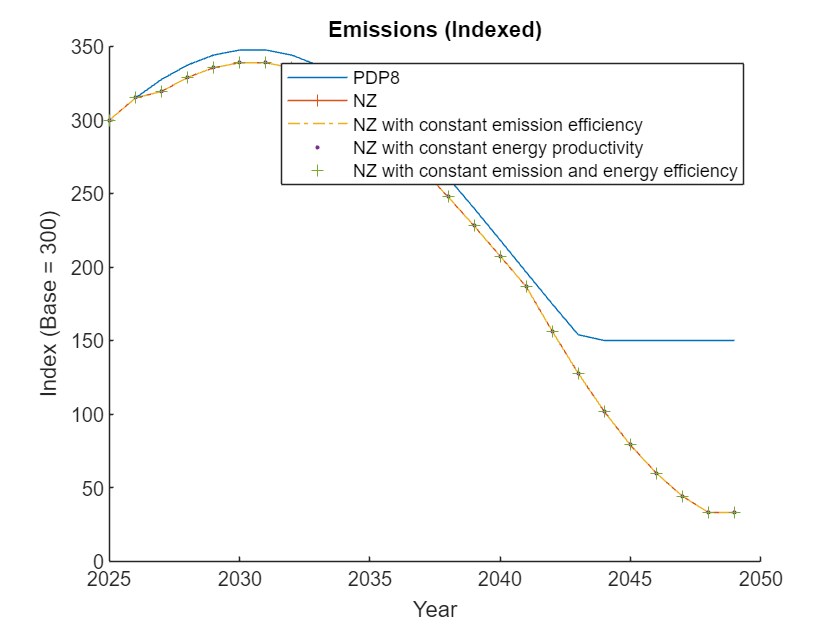

figure('Name', 'Emissions');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.E_1(1:Tplot) ./ ds.E_1(1) * 300, sline);
end
title('Emissions (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index (Base = 300)')
hold off

## Energy Productivity

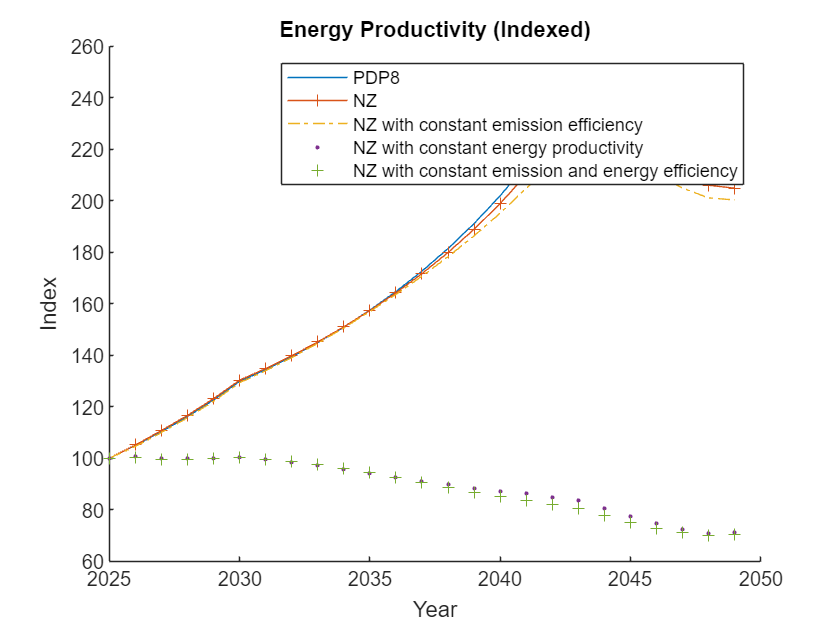

figure('Name', 'Energy productivity');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    productivity = ds.Y_1 ./ (ds.Q_D_2_1 + ds.Q_D_3_1);
    plot(ds.Year(1:Tplot), productivity(1:Tplot) / productivity(1) * 100, sline);
end
title('Energy Productivity (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Cap and Trade Revenues

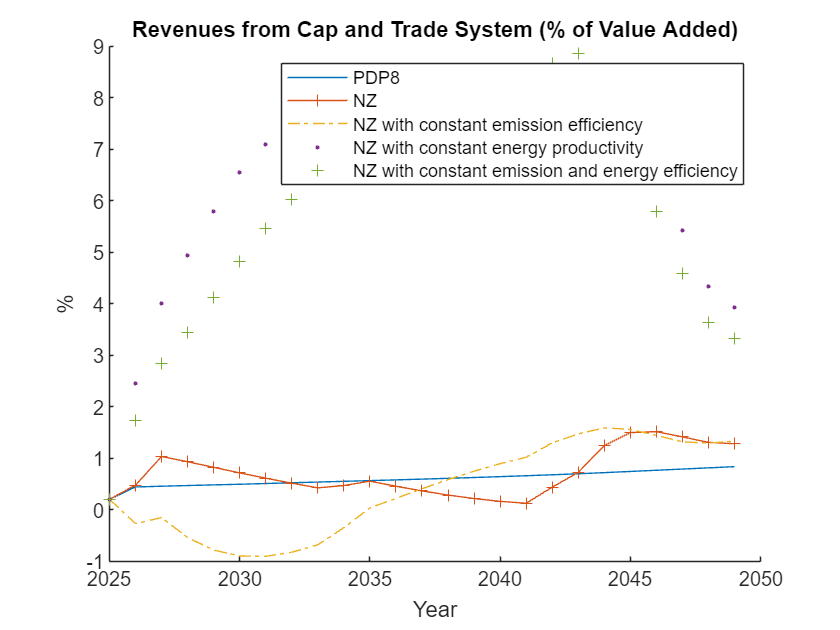

figure('Name', 'Cap and Trade Revenues');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    revenues = ds.PE_1 .* ds.E_1 ./ (ds.Q_1 - ds.Q_I_1) * 100;
    plot(ds.Year(1:Tplot), revenues(1:Tplot), sline);
end
title('Revenues from Cap and Trade System (% of Value Added)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## GDP Growth

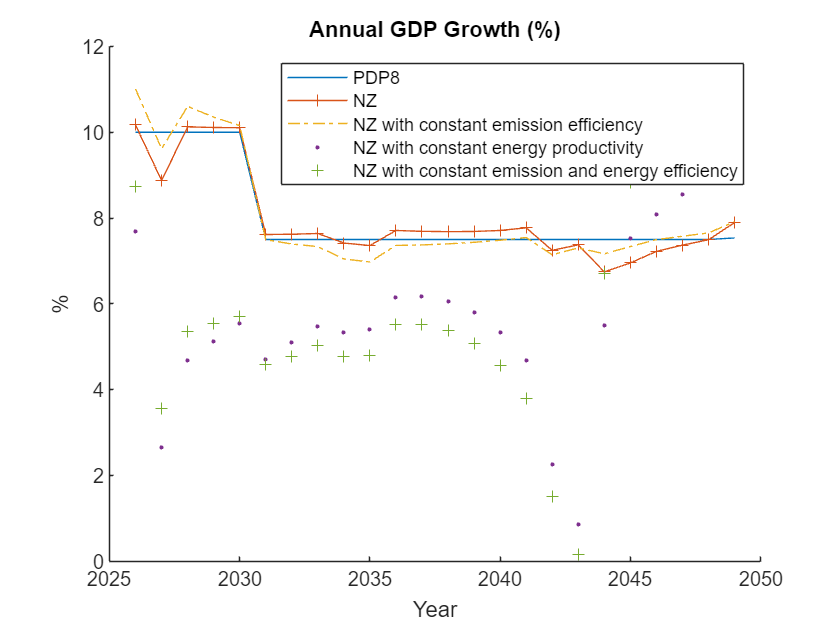

figure('Name', 'GDP Growth');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    growth = (ds.Y_1(2:Tplot) ./ ds.Y_1(1:Tplot-1) - 1) * 100;
    plot(ds.Year(2:Tplot), growth, sline);
end
title('Annual GDP Growth (%)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## Renewable Energy Share (RES)

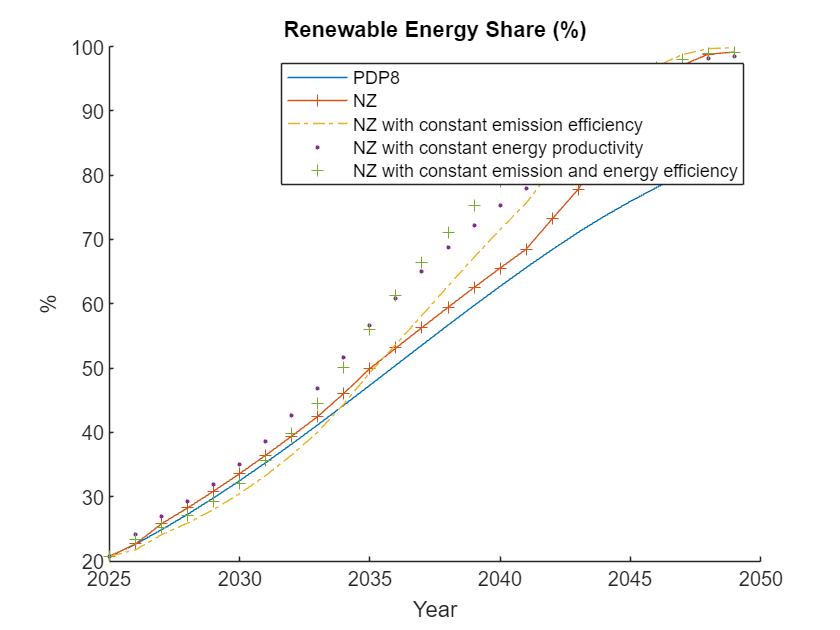

figure('Name', 'Renewable Energy Share');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    res_share = ds.Q_D_3_1 ./ (ds.Q_D_2_1 + ds.Q_D_3_1) * 100;
    plot(ds.Year(1:Tplot), res_share(1:Tplot), sline);
end
title('Renewable Energy Share (%)')
legend(caslegendentries)
xlabel('Year')
ylabel('%')
hold off

## Emission Intensity

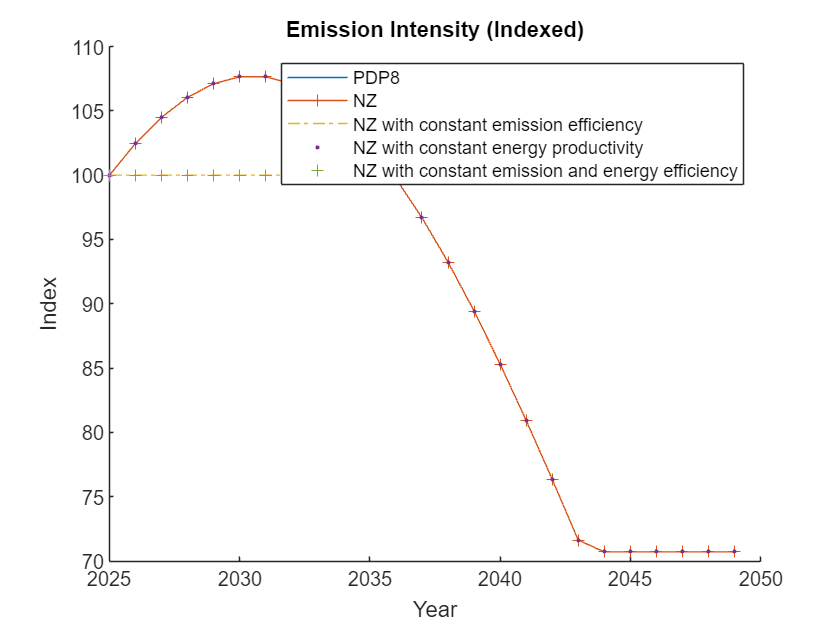

figure('Name', 'Emission Intensity');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.kappaE_2_1(1:Tplot) / ds.kappaE_2_1(1) * 100, sline);
end
title('Emission Intensity (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Energy Efficiency

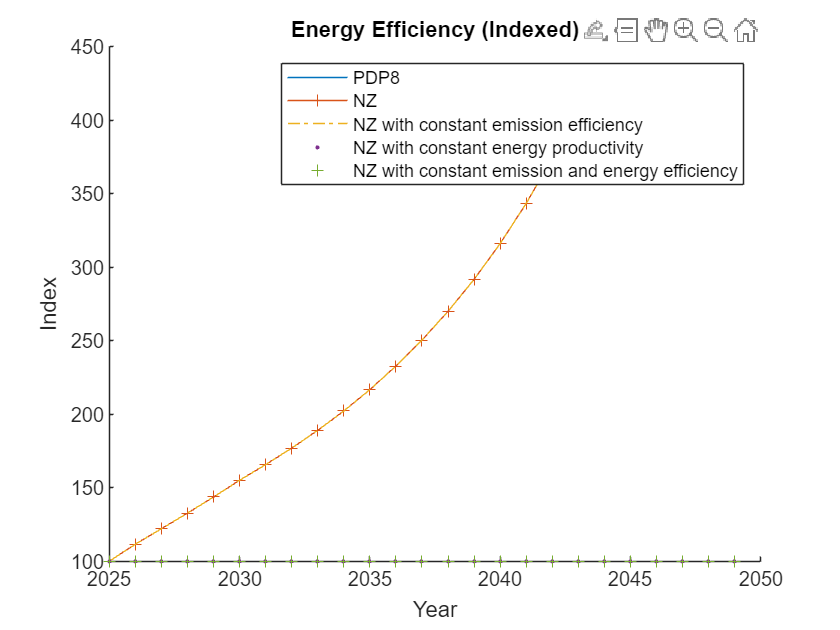

figure('Name', 'Energy Efficiency');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.EE_1(1:Tplot) / ds.EE_1(1) * 100, sline);
end
title('Energy Efficiency (Indexed)')
legend(caslegendentries)
xlabel('Year')
ylabel('Index')
hold off

## Emission Price

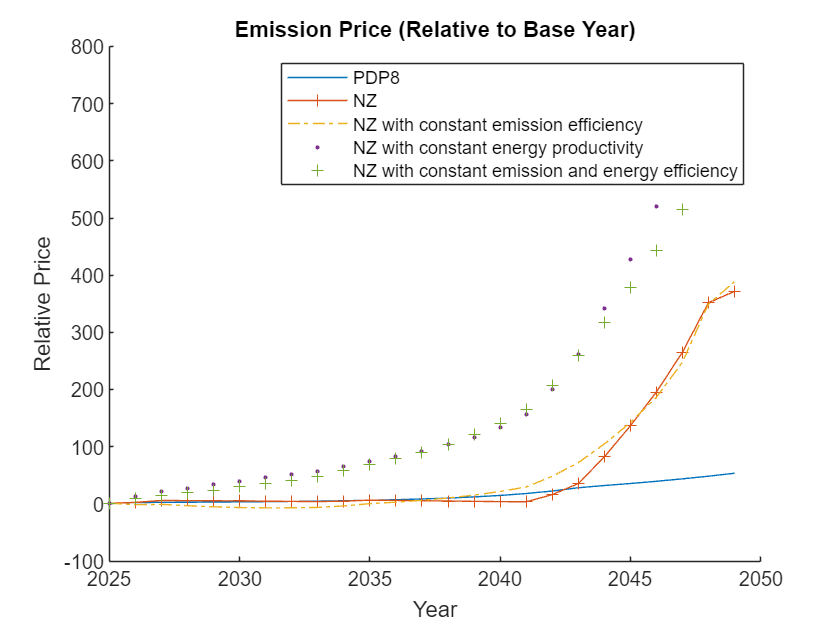

figure('Name', 'Emission Price');
hold on
for iscen = 1:length(casScenarios)
    sScen = casScenarios{iscen};
    ds = dsall.(sScen);
    sline = casLinetypes{iscen};
    plot(ds.Year(1:Tplot), ds.PE_1(1:Tplot) / ds.PE_1(1), sline);
end
title('Emission Price (Relative to Base Year)')
legend(caslegendentries)
xlabel('Year')
ylabel('Relative Price')
hold off

Fossil Energy Production


figure('Name','Fossil Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.Q_2_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Fossil Energy Production'); legend(caslegendentries); hold off

%% 19. Renewable Energy Production
figure('Name','Renewable Energy Production'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), normalize(ds.Q_3_1(1:Tplot)), casLinetypes{iscen});
end
xlabel('Year'); ylabel('Index'); title('Renewable Energy Production'); legend(caslegendentries); hold off

%% 20. Fossil Energy Price (Value Added)
figure('Name','Fossil Energy Price – VA'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    plot(ds.Year(1:Tplot), ds.P_2_1(1:Tplot) * 100, casLinetypes{iscen});
end
xlabel('Year'); ylabel('Price Index'); title('Relative Price of Fossil Energy'); legend(caslegendentries); hold off

%% 21. Sectoral Shares in Value Added -------------------------------------
% Agriculture
figure('Name','VA Share – Agriculture'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareAg = ds.P_1_1 .* ds.Y_1_1 ./ ds.Y_1 * 100;
    plot(ds.Year(1:Tplot), shareAg(1:Tplot), casLinetypes{iscen});
end
xlabel('Year'); ylabel('%'); title('Agriculture Share in VA'); legend(caslegendentries); hold off

% Manufacturing
figure('Name','VA Share – Manufacturing'); hold on
for iscen = 1:numel(casScenarios)
    ds = dsall.(casScenarios{iscen});
    shareMan = ds.P_4_1 .* ds.Y_4_1 ./ ds.Y_1 * 100;

## Conclusion

disp("All scenario plots generated.")

All scenario plots generated.
